# MATLAB 入門之旅

## 2. command

% 把 workspace 的變數全存出來 (i.e. .rda 檔的概念)
% save xxx.mat

% 只存某個變數
% save xxx.mat var_y


% 讀檔(全讀)
% load xxx.mat

% 讀檔(只讀某個變數)
% load xxx.mat var_y

% 清空 workspace
% clear

% 清空 command window
% clc


x =      7
     9


ans =      2     1


## 3. Matlab editor

主要在講 live editor

可以善用 `Section Break` ，把不同段的 code 給隔開。

這樣執行時，就可以用 `Run Section` 來跑單一 section 的 code

不然你一按 run，會整個 script 全部執行

## 4. Array

包含：

- scalar: `x = 4`

- column vector: `x = [7;9]`

- row vector: `x = [7 9] 或 [7, 9]`

- matrix: `x = [5 6 7; 8 9 10] 或 [5, 6, 7; 8, 9, 10]``

`要特別補充的，是 中括號內，都還可以做計算，例如 x = [sqrt(10) pi^2]`

`看 矩陣/向量 的 shape，用 size() 指令`

x = [7; 9]
size(x)

row = 2

col = 1

可將多 output，用 `[ ]` 把他接起來，例如：

x = [7; 9];
[row, col] = size(x)

x =      1     2     3     4


### 等間隔 (間距 1)

x = 1:4

x =      1
     2
     3
     4


這是一個 row vector (可看到 shape 幫你寫好事 1x4)，不需要再幫他加上 `[ ]` 了

如果要轉成 column vector，用轉置符號 `'`

x = 1:4;
x = x'

x =      1
     2
     3
     4


或這樣寫，一步到位也可

x = (1:4)'

x =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000


### 等間隔 (間距自訂)

x = 1:0.5:4 % 1開頭, 以 0.5 當間距, 4結尾

x =          0    0.2500    0.5000    0.7500    1.0000


### 給定總數量，間隔自動算

x = linspace(0, 1, 5) % 0 開頭, 1結尾, 生 5 個數出來

x =     0.2785    0.9575    0.1576
    0.5469    0.9649    0.9706


### 隨機 0~1 的浮點數

x = rand(2, 3) % 2x3 的 N(0,1) 矩陣

### 隨機整數

x = randi([1,20], 5, 7) % 最小值 1, 最大值 20, 產出 5x7 的矩陣

x =      0
     0
     0


### 0 矩陣/向量

x = zeros(3, 1) % 3x1 的 0 column vector

## 5. Indexing into arrays

### 取一個 element

% 對矩陣 A 做 indexing，就是用兩個 element 來做
% matlab 是從 1 開始，不是從 0 開始

% A(1, 3) % 取 (1,3) 這個 element
% A(1, end) % 取第一列，最後一個 column 這個 element
% A(1, end-1) % 可作運算
% A(8) % 少用，他是從第一個 column 開始數，數到底後，接續往第二個 column數，數到第 8 個位置的 element

% 對向量 v 做 indexing
% matlab 是從 1 開始，不是從 0 開始
% v(1) % 取第一個
% v(end) % 取最後一個
% v(end-1) % 取最後數來第二個

### 取多個 element

% 對矩陣 A 做 indexing

% A(1, :) % 取第一個 row
% A(:, 2) % 取第二個 column
% A(1:3, :) % 取第 1~3 個 row
% A(:, end-1:end) % 取最後兩個 column

% 對向量 v 做 indexing
% v(1:5) % 取第 1 ~ 5 個 elements
% v(3:end) % 取 第3個 到 最後一個 elements
% v([2,3,5]) % 取第 2, 3, 5 個 elements

### 修改

就挑出來，塞進去而已

% A(1,2) = 3 % 將 A 的 (1,2) 這個 element 改成 3

### logical indexing

% a = [1, 2, 3, 4, 5]
% a(a>2) % 取出 a>2 的 element
% a(a>2 & a<5)
% a(a<2 | a>4)
% a(a == 3) = 1 % 把 a == 3 的那個位置的 element，用 1 取代

x =      1     3     2     5     3


## 6. operation

就在講

- 向量運算有 broad cast 特性

- 對兩個向量/矩陣 做 `+, -, *, /` 他都默認為矩陣運算 ( `/` 是 inverse)，如果要 element-wise 的乘，那要加上 `.` ，變成 `.* 和 ./ ( .+ 和 .- 就不必了，因為本來就是 element-wise)`

### `取極值 & index`

`這比較重要，要取一個 vector 的 最大值 與 對應位置，可這樣做`

x = [1, 3, 2, 5, 3]

vMax = 5

iMax = 4

[vMax, iMax] = max(x)

x =      1     2     3
     4     5     6


對矩陣就不同了，他是 by column 在取 max：

x = [1,2,3; 4,5,6]

vMax =      4     5     6


iMax =      2     2     2


[vMax, iMax] = max(x)

意思是，三個 column 的 max 分別是 4, 5, 6; 對應的位置都是 2

## `7. 繪圖`

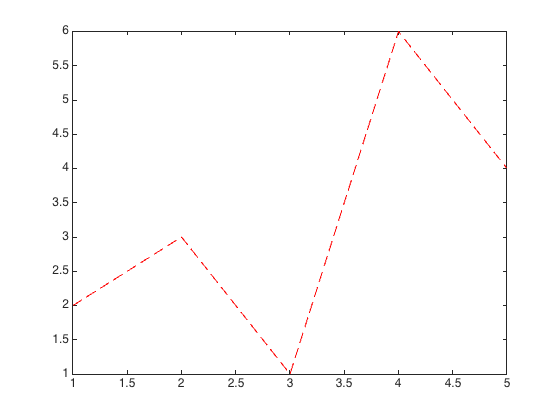

a = [1, 2, 3, 4, 5];
b = [2, 3, 1, 6, 4];
c = [3, 6, 8, 2, 3];
plot(a, b, "r--") % r 是 red, -- 表示線的形狀

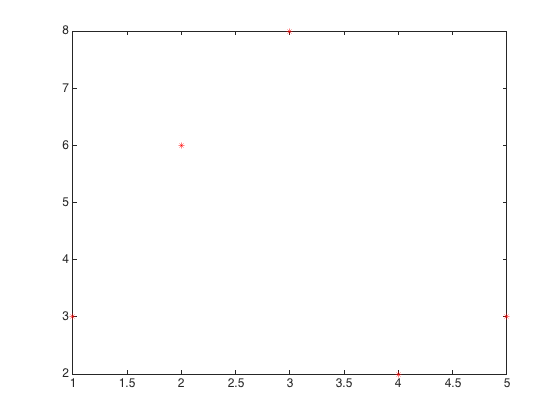

plot(a, c, "r*")

疊在一起的話，要用 `hold on`

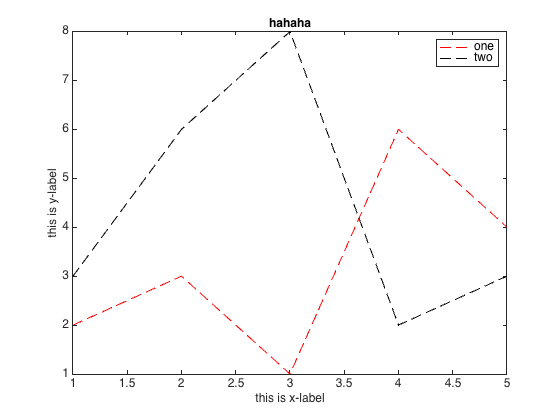

plot(a, b, "r--")
hold on
plot(a, c, "k--") % k = black 的縮寫
title("hahaha")
ylabel("this is y-label")
xlabel("this is x-label")
legend("one", "two")
hold off % 用這個，可以跳脫 hold on 

加參數的寫法，不是用等號，而是用逗號

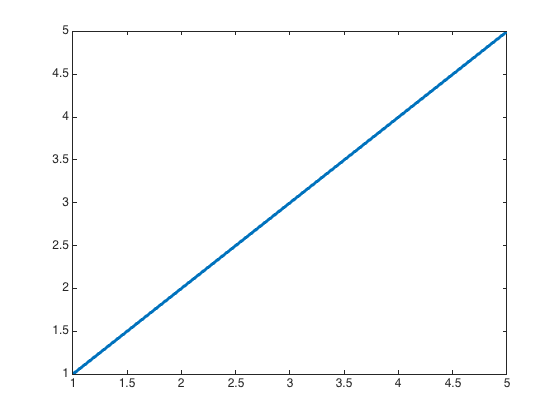

plot(a, "LineWidth", 3)

## 邏輯控制

### if

和 python 的寫法差別，就是不需要加冒號 `:` ，然後，結尾要 `end`

aa = randi([0, 1],1,1)
if aa == 1

aa = 0

    disp("Hi I'm here")
end
if aa == 1
    disp("Hi I'm here")
else
    disp("I'm in else block")
end


I'm in else block


% if...elseif...else...
if aa == 1
    disp("Hi I'm here")
elseif aa == 0
    disp("I'm in elseif block")
else
    disp("It will not happen in this example")
end

I'm in elseif block


### for

和 python 的寫法差別，是他不用 `in` ，而用 `= ; 然後，一樣不用冒號 :`

for c = 1:3
    disp(c)
end

常用做法，是要去 iterate 一個 array 裡面的每一個元素，那要這樣寫

aa = [2, 3, 4, 1, 2]

     1

     2

     3



for idx = 1:length(aa)
    disp(aa(idx))

aa =      2     3     4     1     2


end

     2

     3

     4

     1

     2



## functions (取自另一門課 MATLAB Fundamentals)

先快速講一下 function 的寫法

如果我們有一個 function 叫 `my_func(one_d_array) 他的使用方式是這樣： [a, b] = my_func(one_d_array)`

`其中，a 就是該 array 的 max, b是該 array 的 min`

`那，我們在定義這個 function 時，就只要在最前面加上 function 這個 keyword 就好`

`寫法如下：`

% function [a, b] = my_func(one_d_array)
%     [a, ~] = max(one_d_array);
%     [b, ~] = min(one_d_array);
% end

`(先忽略上面的 comment，假裝他是沒有 comment 的，晚點會解釋)`

`可以看到，他的寫法，output 不需要在 body 中做 return，而是要把名稱和第一行的 output 做對應`

`例如裡面我已經有寫到 a, b 各會被賦值多少了，那這樣就搞定了，不用再寫 return`

`那使用時就如以下這樣用：`

[aa, bb] = my_func([1,2,3,4,5])

再看一個 function 的例子：

% function out = isequal_tol(x, y, tol)
%     res = abs(x-y)

aa = 5

bb = 1

%     if res < tol
%         out = true
%     else
%         out = false
%     end
% end

這個 function，是你給他兩個純量 x, y ，他幫你比較，他們的差異是否小於 tolerance (tol)，如果小於，我就認為他們兩個是近似，就回傳給你 `true` 這樣

所以，實際的用法就會是：

out = isequal_tol(3, 2.8, 0.3)

ans = 5

可以看到，他們的差異值是小於 tolerance = 0.3 的，所以回傳 true

最後，來講講為啥上面要 comment，以及，matlab 是如何呼叫 function 的

當我們呼叫 function 時 (e.g. 呼叫 `my_func()` 這一支)

matlab 的搜尋順序是：

- 這份文件有沒有同名的 variable。如果 my_func 就這麼巧的在這份文件中是個 variable，那你做 my_func(1) 的時候，他會以為你在做 subset 第一個 element 的動作，而不會覺得你是在 call function

- 先在這份文件的 "最底部" ，看看有沒有定義這個 function -> 稱作 local function。所以可以發現，matlab 的慣例是要把 local function 放在最下面，不能用習慣上的先定義再執行的邏輯。這也是為啥我會把上面的部分 comment 掉，因為實際的 function 我已經寫在這份文件的最底部

- 接著，搜尋和這份文件同樣目錄下的 file，有沒有和這支 function 名稱相同的 file。例如 `my_func.m` 檔。所以，我們如果要把 function 定義在一個 file 中，最簡單的做法，是放在相同目錄下。而且，檔名就必須是 function 的名稱，他才搜得到

- 最後，他會去搜尋有可能放 function 的那些資料夾 (例如：內建的 function 所在的資料夾)。如果，我們的 function 所在的 file，不在主程式的相同目錄，那我們就要把這個 function 所在的目錄，註冊進來，他才會去這個資料夾中找找看有沒有要用的 function。設定方式為： `Home` 的 tab下，去點 `Set Path`，然後按 `Add Folder`，把他加進 path 裡。

要確認這個 function/variable，到底在哪有被定義，可以用 `which my_func -all`，他就會列出所有他找得到 `my_func` 的路徑。可以想像，他會用這堆路徑的第一個，來當作這邊要用的 `my_func`()

所以，如果你的 `my_func` ，很不幸的剛好是這份文件的 variable，而不是你要 call 的 function，那可以先用 `clear my_func` 把這個 variable 幹掉，那就可以順利用到 function 了。

那這是我們在其他語言的慣例，先定義 function，再用它

但在 matlab，他的慣例是：

- local function: 要 放在 script 的最下面 (不管是一般 script 或 live script 都一樣)，所以我上面的範例才 comment 掉

- function files: 獨立一個文件來放 function，然後這個文件必須和主程式

最後，來講 function file 要怎麼寫：

- file 名稱，必須和 function 名稱一模一樣 (i.e. `my_func.m` )

- file 的第一行，就是開宗名義的宣告 function: `function [a, b] = my_func(one_d_array)`  

- 這個 function，如果會用到其他 local function，就一樣，把這些 local function 放在這個file的最下面

- 這個 file 只要放在和主程式的同一個路徑下，就可以直接 call 到了，不用 import

看起來是方便，但有些東西我還無法解決：

- 我不能一個 file 裡面，放好多 function 嗎？這樣一個 function 就要一個 file，非常麻煩

- 我一定要把 function file，和主程式放在同一個目錄嗎？不能用絕對路徑去 call 我要的 function file?

ans = my_add(2, 3)

% function example 1

function [a, b] = my_func(one_d_array)
    [a, ~] = max(one_d_array);
    [b, ~] = min(one_d_array);
end

% function example 2
function out = isequal_tol(x, y, tol)
    res = abs(x-y)
    if res < tol
        out = true
    else
        out = false
    end
end